# Import data from text file

Script for importing data from the following text file:

Based on a script auto-generated by MATLAB on 01-Oct-2020 18:13:22

## Set up the Import Options and import the data

opts = delimitedTextImportOptions("NumVariables", 4, "Encoding", "UTF-8");

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Date", "Buyer", "Type", "Amt"];
opts.VariableTypes = ["datetime", "categorical", "categorical", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, ["Buyer", "Type"], "EmptyFieldRule", "auto");
opts = setvaropts(opts, "Date", "InputFormat", "dd-MMM");
opts = setvaropts(opts, "Amt", "TrimNonNumeric", true);
opts = setvaropts(opts, "Amt", "ThousandsSeparator", ",");

% Import the data
shopping = readtable("shopping.csv", opts)

shopping = 482×4 table
     Date     Buyer      Type       Amt
    ______    _____    _________    ___

    01-Jan    Mom      Fuel          50
    02-Jan    Mom      Groceries    120
    03-Jan    Dad      Cafes         10
    04-Jan    Dad      Fuel          40
    04-Jan    Kelly    Groceries    129
    05-Jan    Mom      Cafes         12
    06-Jan    Kelly    Cafes         14
    07-Jan    Kelly    Books        129
    07-Jan    Dad      Groceries    252
    09-Jan    Kelly    Fuel          44
    10-Jan    Dad      Groceries     39
    12-Jan    Mom      Books         20
    13-Jan    Dad      Groceries    132
    14-Jan    Dad      Groceries     79
    16-Jan    Kelly    Groceries    172
    16-Jan    Dad      Music          8


## Clear temporary variables

clear opts

## Building the correlation matrix

To find the correlation matrix between all shopping categories we need to produce a table (or matrix) that has:

- dates as rows

- category types as columns

- the total shopping in that date and type as the values. Note that several people might have shopped in the same day.

For this we will first use unstack, then remove the "Buyer" column, and finally apply groupsummary:

wide_table = unstack(shopping,"Amt","Type")

wide_table = 434×9 table
     Date     Buyer    Books    Cafes    Entertainment    Fuel    Groceries    Music    Restaurants
    ______    _____    _____    _____    _____________    ____    _________    _____    ___________

    01-Jan    Mom       NaN      NaN          NaN          50        NaN        NaN         NaN    
    02-Jan    Mom       NaN      NaN          NaN         NaN        120        NaN         NaN    
    03-Jan    Dad       NaN       10          NaN         NaN        NaN        NaN         NaN    
    04-Jan    Dad       NaN      NaN          NaN          40        NaN        NaN         NaN    
    04-Jan    Kelly     NaN      NaN          NaN         NaN       

wide_table2 = removevars(wide_table,"Buyer")

wide_table2 = 434×8 table
     Date     Books    Cafes    Entertainment    Fuel    Groceries    Music    Restaurants
    ______    _____    _____    _____________    ____    _________    _____    ___________

    01-Jan     NaN      NaN          NaN          50        NaN        NaN         NaN    
    02-Jan     NaN      NaN          NaN         NaN        120        NaN         NaN    
    03-Jan     NaN       10          NaN         NaN        NaN        NaN         NaN    
    04-Jan     NaN      NaN          NaN          40        NaN        NaN         NaN    
    04-Jan     NaN      NaN          NaN         NaN        129        NaN         NaN    
    05-Jan     NaN       12          NaN         NaN        NaN 

shopping_per_category = groupsummary(wide_table2,"Date","sum")

shopping_per_category = 338×9 table
     Date     GroupCount    sum_Books    sum_Cafes    sum_Entertainment    sum_Fuel    sum_Groceries    sum_Music    sum_Restaurants
    ______    __________    _________    _________    _________________    ________    _____________    _________    _______________

    01-Jan        1              0           0                 0              50              0             0               0       
    02-Jan        1              0           0                 0               0            120             0               0       
    03-Jan        1              0          10                 0               0              0             0               0

Now we can build the correlation matrix using columns 3 to 9 of the resulting table:

corr_matrix = corrcoef(shopping_per_category{:,3:9})

corr_matrix =     1.0000    0.0008   -0.0370   -0.0819   -0.0776   -0.0340   -0.0708
    0.0008    1.0000    0.0606    0.0222   -0.0920    0.0494    0.0255
   -0.0370    0.0606    1.0000   -0.0206   -0.0769    0.0142   -0.0739
   -0.0819    0.0222   -0.0206    1.0000   -0.1087   -0.0675   -0.2182
   -0.0776   -0.0920   -0.0769   -0.1087    1.0000   -0.0578   -0.1866
   -0.0340    0.0494    0.0142   -0.0675   -0.0578    1.0000    0.0556
   -0.0708    0.0255   -0.0739   -0.2182   -0.1866    0.0556    1.0000


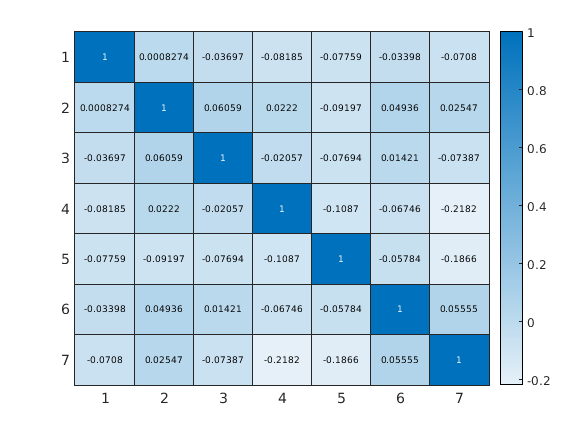

heatmap(corr_matrix)

We observe very low correlation values. Can we do better? If we examine shoppint_per_category we see many cells with zeros. Let's do something about it.

## A better correlation matrix

Let's see if we can obtain higher correlation values if we group shopping_per_category by month insted of by day:

shopping_per_category2 = groupsummary(shopping_per_category,"Date","month","sum")

shopping_per_category2 = 12×10 table
    month_Date    GroupCount    sum_GroupCount    sum_sum_Books    sum_sum_Cafes    sum_sum_Entertainment    sum_sum_Fuel    sum_sum_Groceries    sum_sum_Music    sum_sum_Restaurants
    __________    __________    ______________    _____________    _____________    _____________________    ____________    _________________    _____________    ___________________

     Jan-2021         23              28               169               36                  271                 209               2147                15                    0        
     Feb-2021         22              26               476               

corr_matrix2 = corrcoef(shopping_per_category2{:,4:10})

corr_matrix2 =     1.0000   -0.0439    0.2495   -0.2715    0.0943   -0.2433   -0.5260
   -0.0439    1.0000   -0.2967    0.4289    0.2276    0.8367    0.1312
    0.2495   -0.2967    1.0000   -0.5575    0.0006   -0.2058   -0.4918
   -0.2715    0.4289   -0.5575    1.0000   -0.2329    0.3450    0.1218
    0.0943    0.2276    0.0006   -0.2329    1.0000    0.0261    0.4170
   -0.2433    0.8367   -0.2058    0.3450    0.0261    1.0000    0.2106
   -0.5260    0.1312   -0.4918    0.1218    0.4170    0.2106    1.0000


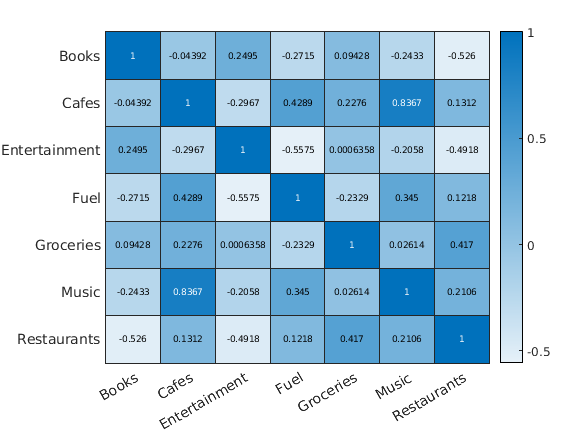

xvalues = {'Books', 'Cafes', 'Entertainment', 'Fuel', 'Groceries', 'Music', 'Restaurants'};
yvalues = {'Books', 'Cafes', 'Entertainment', 'Fuel', 'Groceries', 'Music', 'Restaurants'};
heatmap(xvalues, yvalues, corr_matrix2)

This is much better. Now we can see a high correlation between Cafes and Music.

Note that the next highest correlation is negative between Entertainment and Fuel.